## Exercici 3. 

Es pretén dissenyar un algoritme simple d’auto-enfoc. La idea és comparar varies imatges d’una mateixa escena adquirides movent l’enfoc de la càmera (que se suposa motoritzat).  Per exemple en la següent seqüència d’imatges (fig1) es pot veure com al anar variant la distància focal de la lent s’obtenen imatges amb enfoc en diferents profunditats. Les imatges les trobareu annexes a aquest document.

- El primer que farem és llegir les imatges i les convertim a nivell de grisos (rgb2gray).

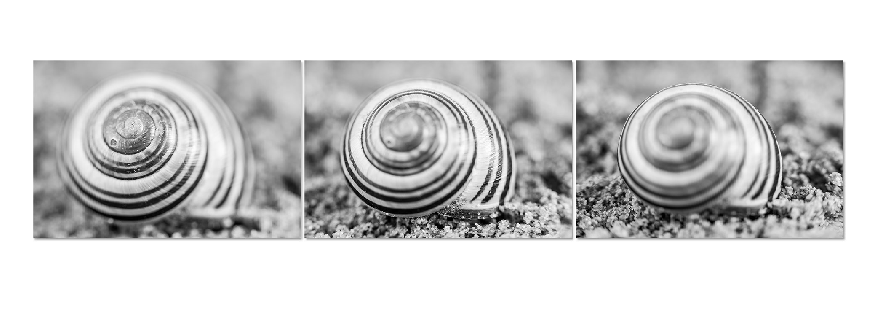

img1 = rgb2gray(imread("_61A5845.jpg"));
img2 = rgb2gray(imread("_61A5855.jpg"));
img3 = rgb2gray(imread("_61A5861.jpg"));
montage([img1,img2,img3]);

        2.  Passarem un filtre derivatiu (*sobel* o similar) per detectar els contorns verticals Sy i horitzontals Sx. Vigileu el tipus de la imatge doncs no us trunqui els valors negatius o valors més grans que 255.

hv = fspecial('sobel');
hh = hv';
img1x = imfilter(double(img1),hv);
img1y = imfilter(double(img1),hh);
img2x = imfilter(double(img2),hv);
img2y = imfilter(double(img2),hh);
img3x = imfilter(double(img3),hv);
img3y = imfilter(double(img3),hh);
%montage([img1x,img2x,img3x]);
%montage([img1y,img2y,img3y]);

        3.  Com que en aquesta aplicació és indiferent si el contorn és positiu o negatiu, vertical o horitzontal, calcularem el valor absolut de Sx i Sy, i els sumarem.

img1sum = abs(img1x)+abs(img1y);
img2sum = abs(img2x)+abs(img2y);
img3sum = abs(img3x)+abs(img3y);
%montage([img1sum,img2sum,img3sum]);

        4.  Calcularem un valor ***m ***de mèrit de l’enfoc i compararem els resultats de les tres imatges. La imatge que proporcioni un valor ***m*** més alt és la que es considerarà de millor enfoc. La funció que calcula el valor ***m*** queda a la vostre elecció, però seria interessant que ponderes amb major pes els píxels centrals de la imatge que els de la perifèria.

format shortG
merit(img1sum,100,0)

ans =         23310


merit(img2sum,100,0)

ans =         25517


merit(img3sum,100,0)

ans =         14907


Podem veure que la imatge amb més mèrit d'enfoc és la segona (enfoc a mitja distància), la segona amb més mèrit d'enfoc és la primera (enfoc molt proper) i la pitjor de les tres és la tercera (enfoc passat l'objecte). Aquest resultat és coherent, ja que la segona imatge és la que millor enfoca l'objecte, la primera imatge té un bon mèrit d'enfoc ja que el centre d'aquesta està enfocat, i la funció té més en compte el centre que la perifèria de la imatge, és per això mateix que la tercera imatge té tan baix mèrit, el centre és el que està desenfocat.

Ara faré la prova amb una imatge propia:

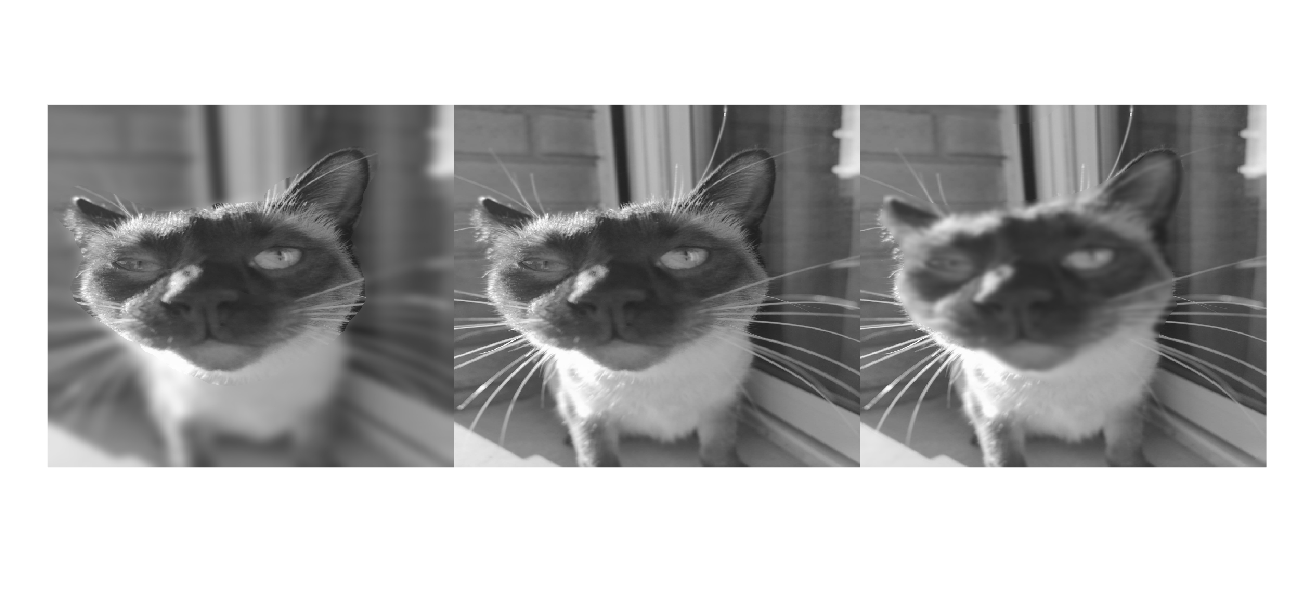

img1 = rgb2gray(imread("cocobfocella.jpg"));
img2 = rgb2gray(imread("cocob.jpg"));
img3 = rgb2gray(imread("cocobunfoc.jpg"));
montage([img1,img2,img3]);

hv = fspecial('sobel');
hh = hv';
img1x = imfilter(double(img1),hv);
img1y = imfilter(double(img1),hh);
img2x = imfilter(double(img2),hv);
img2y = imfilter(double(img2),hh);
img3x = imfilter(double(img3),hv);
img3y = imfilter(double(img3),hh);
img1sum = abs(img1x)+abs(img1y);
img2sum = abs(img2x)+abs(img2y);
img3sum = abs(img3x)+abs(img3y);
merit(img1sum,300,0)

ans =         12464


merit(img2sum,300,0)

ans =         14269


merit(img3sum,300,0)

ans =        7275.3


Amb les fotos desenfocades a mà he intentat recrear les donades per l'exercici. El resultat es el mateix, la imatge enfocada és la que té mèrit d'enfoc més alt, la que enfoca proper queda amb un valor molt proper i la imatge amb l'objecte desenfocat té un mèrit d'enfoc molt més baix. El motiu que la primera i segona imatge tinguin un mèrit tan semblant pot ser perquè la funció mèrit té en compte del centre molt més que la perifèria, per tal de donar més pes a què l'objecte central estigui enfocat.

Nota: La funció que he fet servir necessita la mu i sigma de la gaussiana com a paràmetres, per aquest exercici he fet servir sigma = 100 i mu = 0 per la primera imatge i sigma = 300 i mu = 0 , però tant si l'objecte d'interès no està al centre de la imatge o la mida d'aquest varia molt, ajustant aquests paràmetres adequadament per la imatge en qüestió tindríem altre cop un bon mesurador de l'enfocament de la imatge.

function m = merit(img,sigma,mu)
    y = size(img,1); %agafem la mida de la imatge objectiu
    x = size(img,2);
    vecx = linspace((-x/2),(x/2),x);
    vecy = linspace((-y/2),(y/2),y);
    [mx, my] = meshgrid(vecx,vecy); %construim una meshgrid centrada en el centre de la imatge
    gaussian = (1/(sigma*sqrt(2*pi)))*exp((-1/2)*((sqrt(mx.^2+my.^2)-mu)/sigma).^2); %fem una gaussiana bidimensional en una matriu
    m = sum(dot(img,gaussian)); %multipliquem la imatge amb la matriu gaussiana i sumem els elements
    end